% Extract envelope and VAR model

%% Parameters


% Filtering

if ~exist('filterOrder', 'var') filterOrder = 100; end 
if ~exist('fcut1','var') fcut1 = 60; end
if ~exist('fcut2','var') fcut2 = 80; end
if ~exist('fstop1','var') fstop1 = 57; end % Stopband attenuation
if ~exist('fstop2','var') fstop2 = 82; end
if ~exist('fs','var') fs = 500;  end
if ~exist('fn','var') fn  = fs/2; end % Nyquist
if ~exist('f','var') f = [0 fstop1 fcut1 fcut2 fstop2 fn]/fn; end % Bandpass frequency with attenuation
if ~exist('a','var') a = [0 0 1 1 0 0]; end % Filter moving average components
if ~exist('w','var') w   = [700 1 700]; end % Weights of the filter 
if ~exist('fbin','var') fbin = 1024; end% Number of frequency bins
if ~exist('Band','var') Band = [fcut1 fcut2]; end

% Epoching 

if ~exist('trange','var') trange = [10 80]; end % Time series range
if ~exist('wsize','var') wsize = [0 10]; end % Epoch size
if ~exist('wstep','var') wstep = 5; end % Step between epochs
if ~exist('multitrial','var') multitrial = true; end

% Import EEGlab data 
[fname, fpath, dataset] = CIFAR_filename('preproc', false, ...
    'subject','JuRo'); 
datapath = fullfile('~','projects','CIFAR','data_fun', ... 
    'JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage_pick.mat')

datapath = '~/projects/CIFAR/data_fun/JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage_pick.mat'

dataset = load(datapath)

dataset = struct with fields:
    data: [5×104999 double]


EEG = pop_loadset(fname, fpath);

pop_loadset(): loading file ~/projects/CIFAR/source_data/iEEG_10/subjects/JuRo/EEGLAB_datasets/bipolar_montage/JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage.set ...
Reading float file '~/projects/CIFAR/source_data/iEEG_10/subjects/JuRo/EEGLAB_datasets/bipolar_montage/JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage.fdt'...


X = 	1.0e+-3 *

    0.0450    0.0375    0.0362    0.0388    0.0374    0.0316    0.0316    0.0307    0.0292    0.0277    0.0305    0.0313    0.0342    0.0381    0.0389    0.0410    0.0469    0.0570    0.0576    0.0551    0.0571    0.0633    0.0675    0.0638    0.0567    0.0546    0.0572    0.0505    0.0436    0.0413    0.0322    0.0281    0.0292    0.0256    0.0248    0.0220    0.0158    0.0161    0.0172    0.0162    0.0116    0.0092    0.0152    0.0197    0.0228    0.0244    0.0185    0.0134    0.0137    0.0218
   -0.0118   -0.0083   -0.0091   -0.0110   -0.0118   -0.0136   -0.0120   -0.0083   -0.0116   -0.0139   -0.0107   -0.0115   -0.0189   -0.0252   -0.0247   -0.0231   -0.0208   -0.0179   -0.0185   -0.0194   -0.0185   -0.0173   -0.0198   -0.0206   -0.0172   -0.0144   -0.0094   -0.0056   -0.0038   -0.0009   -0.0031   -0.0104   -0.0172   -0.0192   -0.0168   -0.0151   -0.0106   -0.0059   -0.0048   -0.0049   -0.0063   -0.0094   -0.0121   -0.0096   -0.0092   -0.0085   -0.0050   -0.0027   

X = dataset.data

X = 	1.0e+-3 *

    0.0450    0.0375    0.0362    0.0388    0.0374    0.0316    0.0316    0.0307    0.0292    0.0277    0.0305    0.0313    0.0342    0.0381    0.0389    0.0410    0.0469    0.0570    0.0576    0.0551    0.0571    0.0633    0.0675    0.0638    0.0567    0.0546    0.0572    0.0505    0.0436    0.0413    0.0322    0.0281    0.0292    0.0256    0.0248    0.0220    0.0158    0.0161    0.0172    0.0162    0.0116    0.0092    0.0152    0.0197    0.0228    0.0244    0.0185    0.0134    0.0137    0.0218
   -0.0118   -0.0083   -0.0091   -0.0110   -0.0118   -0.0136   -0.0120   -0.0083   -0.0116   -0.0139   -0.0107   -0.0115   -0.0189   -0.0252   -0.0247   -0.0231   -0.0208   -0.0179   -0.0185   -0.0194   -0.0185   -0.0173   -0.0198   -0.0206   -0.0172   -0.0144   -0.0094   -0.0056   -0.0038   -0.0009   -0.0031   -0.0104   -0.0172   -0.0192   -0.0168   -0.0151   -0.0106   -0.0059   -0.0048   -0.0049   -0.0063   -0.0094   -0.0121   -0.0096   -0.0092   -0.0085   -0.0050   -0.0027   

EEG.data = X 

EEG = struct with fields:
             setname: 'JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage'
            filename: 'JuRo_freerecall_rest_baseline_1_preprocessed_BP_montage.set'
            filepath: '~/projects/CIFAR/source_data/iEEG_10/subjects/JuRo/EEGLAB_datasets/bipolar_montage'
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Original file: D:\ECoG\Free_Recall_RAWDATA\JuRo\edf\RUN1\JuRo_free_recall.edf'
              nbchan: 75
              trials: 1
                pnts: 104999
               srate: 500
                xmin: 0
                xmax: 209.9960
               times: [1×104999 double]
                data: [5×104999 double]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×75 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
          

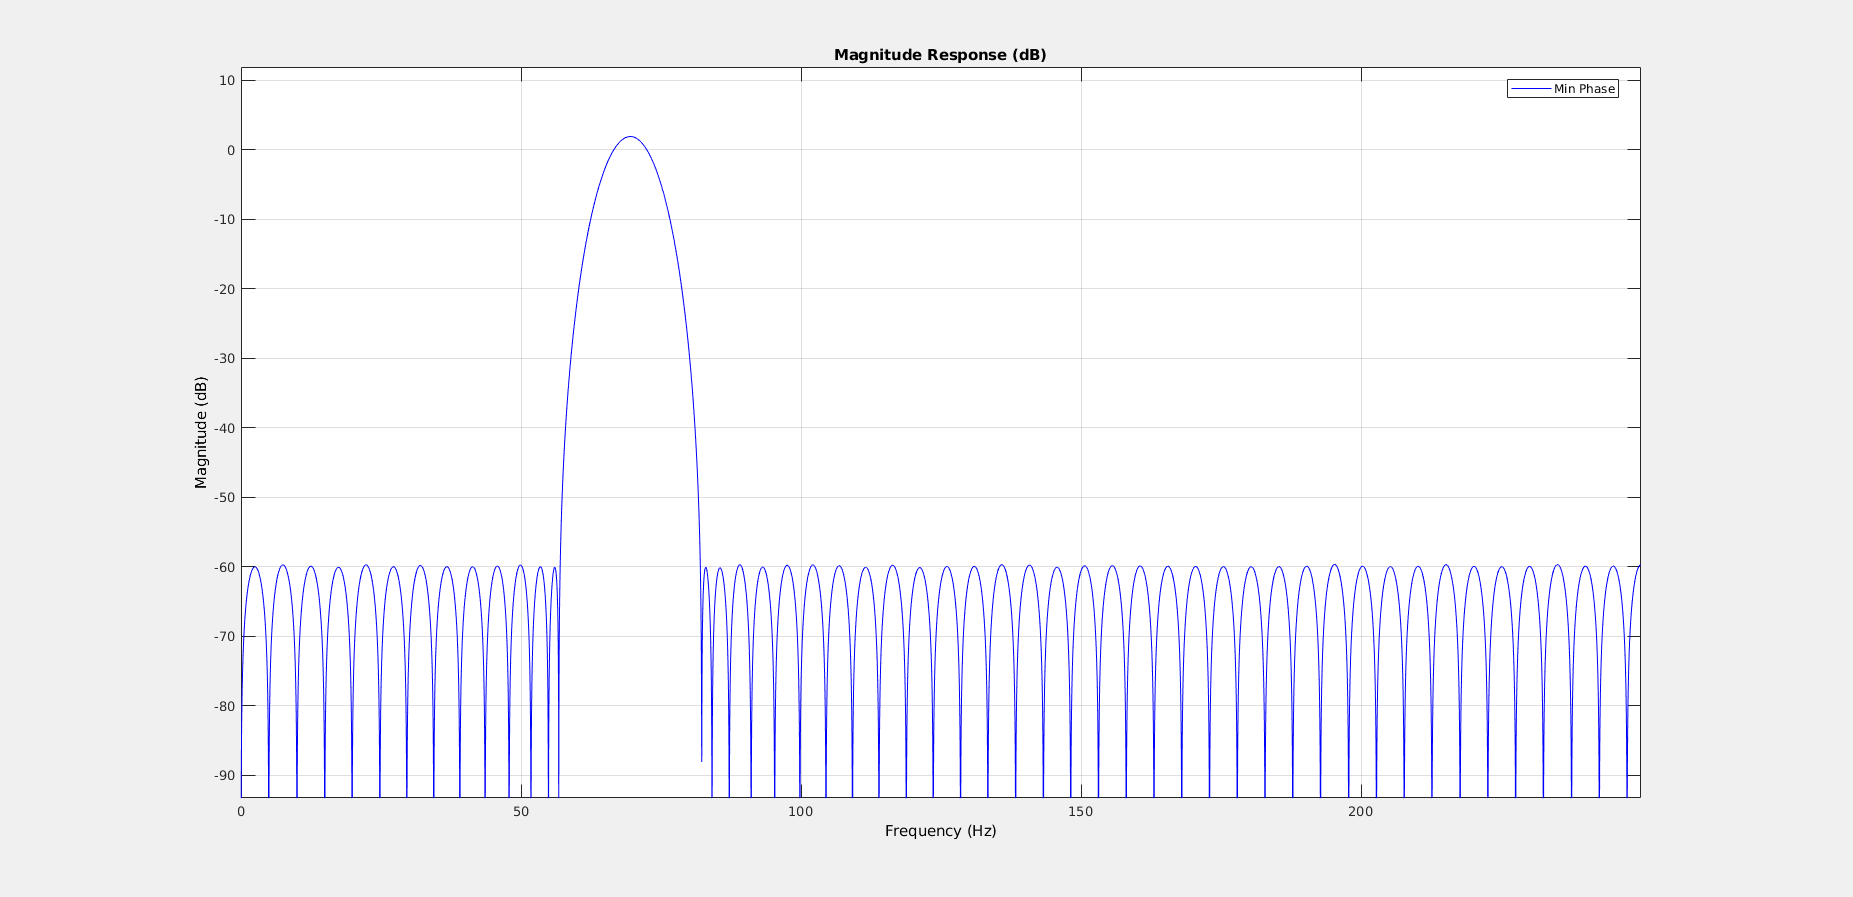

% Envelope extraction

% Bandpass filter
bpFilt   = firgr(filterOrder, f, a, w, 'minphase');

% Magnitude response
hfvt = fvtool(bpFilt,'Fs', fs,...
              'MagnitudeDisplay', 'Magnitude (dB)',...
              'legend','on');
legend(hfvt,'Min Phase');

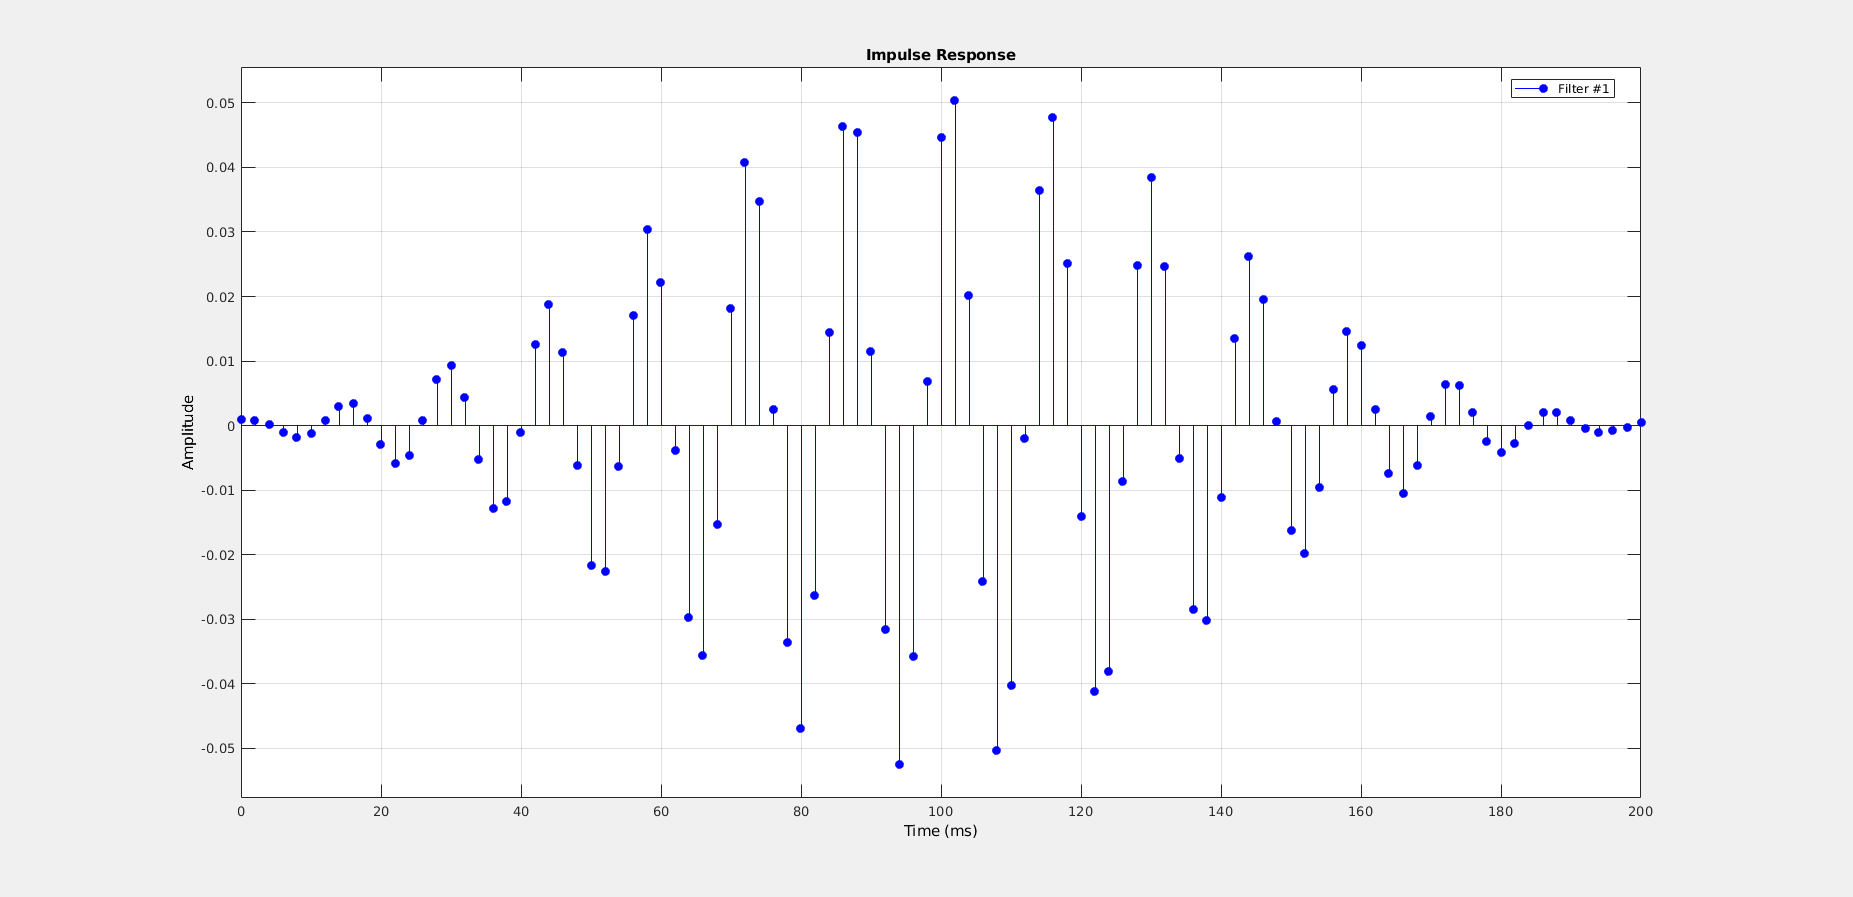


% Impulse response
fvtool(bpFilt, 'Fs', fs, ...
              'Analysis', 'Impulse', ...
              'legend', 'on', ...
              'Arithmetic', 'fixed');

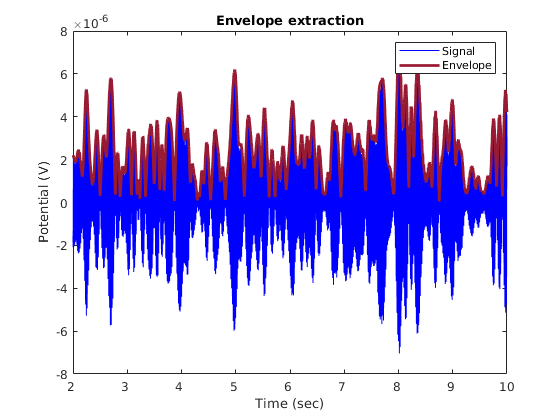

          
% Extract envelope from hilbert transform on filtered data
[envelope, tsdata_filt] = tsdata2env(X, bpFilt);

trange = 1000:5000; chanum= 3;
plot_envelope(tsdata_filt,envelope,trange, chanum, fs)


% Assign in new EEG structure
EEG_envelope = EEG;
EEG_envelope.data = envelope;

EEG_filt = EEG;
EEG_filt.data = tsdata_filt;

%% Epoching 

outEEG_env = eeg_regepochs(EEG_envelope, 'recurrence', wstep, 'limits', wsize); % Epoch envelope

The input dataset will be split into 41 epochs of 10 s
Epochs will overlap by 50%.
Inserting 41 type 'X' events: .......................................40
.
Sorting the event table.
Splitting the data into 41 10.00-s epochs
pop_epoch():41 epochs selected
Epoching...
pop_epoch():40 epochs generated
eeg_checkset warning: number of columns in data (5) does not match the number of channels (75): corrected
eeg_checkset warning: number of channels different in data and channel file/struct: channel file/struct removed


         number of channels. Channel information have been removed.
eeg_checkset: found empty values for field 'duration' (filling with 0)
eeg_checkset: found empty values for field 'urevent'
              filling with values of other events in the same epochs
pop_epoch(): checking epochs for data discontinuity


epochEEG_filt = eeg_regepochs(EEG_filt, 'recurrence', wstep, 'limits', wsize); % Epoch filtered data

The input dataset will be split into 41 epochs of 10 s
Epochs will overlap by 50%.
Inserting 41 type 'X' events: .......................................40
.
Sorting the event table.
Splitting the data into 41 10.00-s epochs
pop_epoch():41 epochs selected
Epoching...
pop_epoch():40 epochs generated
eeg_checkset warning: number of columns in data (5) does not match the number of channels (75): corrected
eeg_checkset warning: number of channels different in data and channel file/struct: channel file/struct removed


         number of channels. Channel information have been removed.
eeg_checkset: found empty values for field 'duration' (filling with 0)
eeg_checkset: found empty values for field 'urevent'
              filling with values of other events in the same epochs
pop_epoch(): checking epochs for data discontinuity


epochEEG = eeg_regepochs(EEG, 'recurrence', wstep, 'limits', wsize); % Epoch initial data

The input dataset will be split into 41 epochs of 10 s
Epochs will overlap by 50%.
Inserting 41 type 'X' events: .......................................40
.
Sorting the event table.
Splitting the data into 41 10.00-s epochs
pop_epoch():41 epochs selected
Epoching...
pop_epoch():40 epochs generated
eeg_checkset warning: number of columns in data (5) does not match the number of channels (75): corrected
eeg_checkset warning: number of channels different in data and channel file/struct: channel file/struct removed


         number of channels. Channel information have been removed.
eeg_checkset: found empty values for field 'duration' (filling with 0)
eeg_checkset: found empty values for field 'urevent'
              filling with values of other events in the same epochs
pop_epoch(): checking epochs for data discontinuity



% Extract epoched time series
epochedEnvelope = outEEG_env.data; 
epochedTsdata_filt = epochEEG_filt.data;
epochX = epochEEG.data;

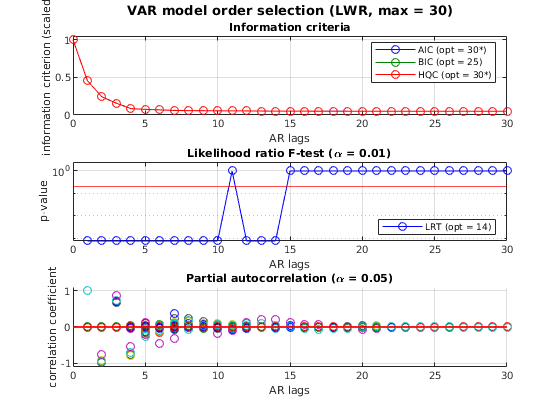


VAR info:
    observables       = 5
    model order       = 14
    AR spectral norm  = 0.9727      stable (autocorrelation decay ~ 651)
    residuals covariance matrix     symmetric, pos. def. (mii = 0.0028, uniform = 2.3795)



tic 
[VARmodel, VARmoest] = VARmodeling(epochedEnvelope, 'momax', 30, 'mosel', 4, 'multitrial', multitrial);

toc

Elapsed time is 9.613055 seconds.
